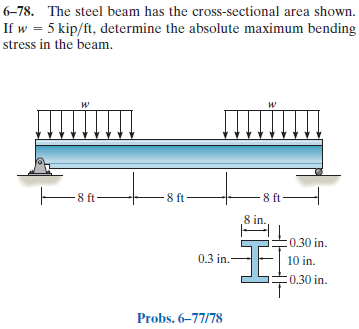

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-78P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-78P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rb', 24*u.ft);
b = b.add('distributed', 'force', -5*u.kip/u.ft, [0 8]*u.ft);
b = b.add('distributed', 'force', -5*u.kip/u.ft, [16 24]*u.ft);
b.L = 24*u.ft;

# section properties

yc = [10/2+0.30/2 0 -10/2-0.30/2]*u.in;
Ac = [8*0.30 0.30*10 8*0.30]*u.in^2;
Ic = [8*0.30^3 0.30*10^3 8*0.30^3]/12*u.in^4;
[yn Qn In] = beam.neutral_axis(yc, Ac, Ic);
b.I = rewrite(sum(In), u.ft);

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{540000\,x\,\left(x^{3}-32\,x^{2}\,\mathrm{ft}+7168\,{\mathrm{ft}}^{3}\right)}{19043\,\text{E}}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{5}} & \text{ if }x\leq 8\,\mathrm{ft}\\ \frac{69120000\,\left(3\,x^{2}-72\,x\,\mathrm{ft}+32\,{\mathrm{ft}}^{2}\right)}{19043\,\text{E}}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{3}} & \text{ if }x\in \left(8\,\mathrm{ft},16\,\mathrm{ft}\right]\\ -\frac{540000\,\left(x-24\,\mathrm{ft}\right)\,\left(x^{3}-40\,x^{2}\,\mathrm{ft}+192\,x\,{\mathrm{ft}}^{2}-2560\,{\mathrm{ft}}^{3}\right)}{19043\,\text{E}}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{5}} & \text{ if }16\,\mathrm{ft}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{2160000\,\left(x^{3}-24\,x^{2}\,\mathrm{ft}+1792\,{\mathrm{ft}}^{3}\right)}{19043\,\text{E}}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{5}} & \text{ if }x\leq 8\,\mathrm{ft}\\ \frac{414720000\,\left(x-12\,\mathrm{ft}\right)}{19043\,\text{E}}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{3}} & \text{ if }x\in \left(8\,\mathrm{ft},16\,\mathrm{ft}\right]\\ -\frac{2160000\,\left(x^{3}-48\,x^{2}\,\mathrm{ft}+576\,x\,{\mathrm{ft}}^{2}-1792\,{\mathrm{ft}}^{3}\right)}{19043\,\text{E}}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{5}} & \text{ if }16\,\mathrm{ft}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -\frac{5\,x\,\left(x-16\,\mathrm{ft}\right)}{2}\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\leq 8\,\mathrm{ft}\\ 160\,\mathrm{ft}\,\mathrm{kip} & \text{ if }x\in \left(8\,\mathrm{ft},16\,\mathrm{ft}\right)\\ -\frac{5\,\left(x-8\,\mathrm{ft}\right)\,\left(x-24\,\mathrm{ft}\right)}{2}\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }16\,\mathrm{ft}\leq x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} -5\,\left(x-8\,\mathrm{ft}\right)\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\leq 8\,\mathrm{ft}\\ 0 & \text{ if }x\in \left(8\,\mathrm{ft},16\,\mathrm{ft}\right)\\ -5\,\left(x-16\,\mathrm{ft}\right)\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }16\,\mathrm{ft}\leq x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} -5\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\leq 8\,\mathrm{ft}\\ 0 & \text{ if }x\in \left(8\,\mathrm{ft},16\,\mathrm{ft}\right)\\ -5\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }16\,\mathrm{ft}\leq x \end{array}\right.$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} \mathrm{Ra} & 40\,\mathrm{kip}\\ \mathrm{Rb} & 40\,\mathrm{kip} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

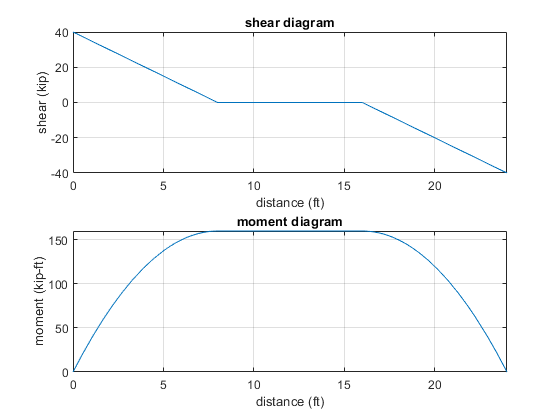

beam.shear_moment(m, v, [0 b.L], {'kip' 'ft'});

# absolute maximum bending stress

M_max = m(8*u.ft)

$$M\_max = 160\,\mathrm{ft}\,\mathrm{kip}$$

C = (10+2*0.30)*u.in/2;
b.I = rewrite(b.I, u.in);
sigma_max = rewrite(M_max*C/b.I, u.ksi);
sigma_max_vpa = vpa(sigma_max, 4) %#ok<NASGU> 

$$sigma\_max\_vpa = 66.8\,\mathrm{ksi}$$

# clean up

addvar(y);
assume(old_assum);
clear old_assum;
clear sigma_max_vpa;